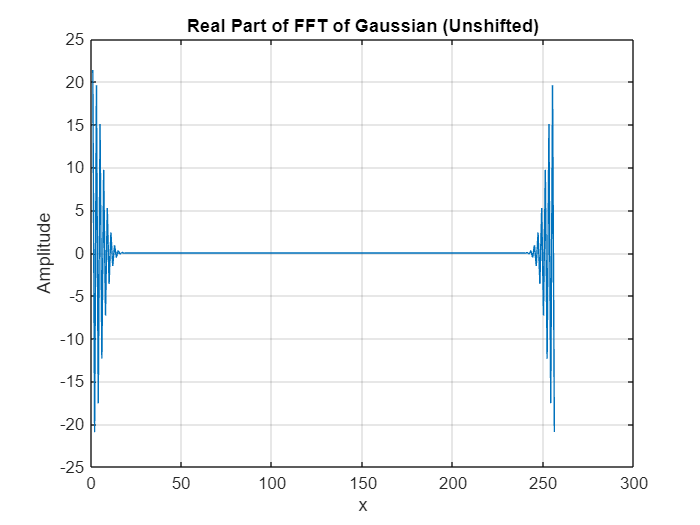

% 1. 

x = linspace(-15, 15, 257);
x = x(1:256); 
y = exp(-0.5 * x.^2);

Y = fft(y);

figure;
plot(real(Y));
title('Real Part of FFT of Gaussian (Unshifted)');
xlabel('x');
ylabel('Amplitude');
grid on;

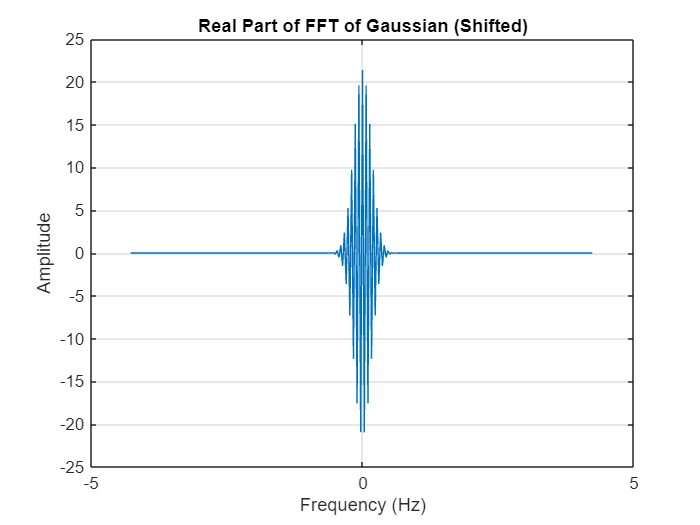


Y_shifted = fftshift(Y);
N = length(y);
fs = N / 30; 
f = (-N/2 : N/2-1) * (fs/N); 
figure;
plot(f, real(Y_shifted));
title('Real Part of FFT of Gaussian (Shifted)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;



fprintf('The Fourier transform of a Gaussian is a Gaussian.\n');

The Fourier transform of a Gaussian is a Gaussian.


fprintf('The reason the initial plot doesn''t look right is due to how the FFT algorithm organizes its output.\n\n');

The reason the initial plot doesn't look right is due to how the FFT algorithm organizes its output.



fprintf('The output is not ordered from most negative to most positive frequency. Instead, it is arranged as:\n');

The output is not ordered from most negative to most positive frequency. Instead, it is arranged as:


fprintf('The negative frequency components, which ''wrap around'' to the end of the array.\n\n');

The negative frequency components, which 'wrap around' to the end of the array.



fprintf('The fix is to use the fftshift() function. This function rearranges the array to place\n');

The fix is to use the fftshift() function. This function rearranges the array to place


fprintf('the zero-frequency component in the center, which is the conventional way to view a frequency spectrum.\n');

the zero-frequency component in the center, which is the conventional way to view a frequency spectrum.


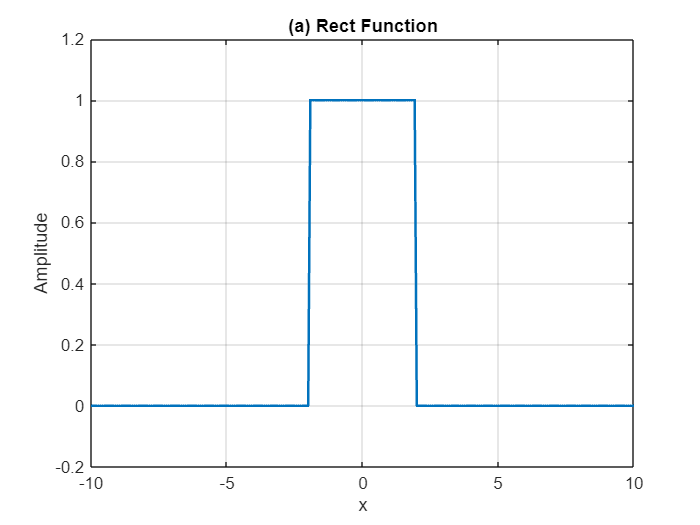

% 2.

N = 256;
x = linspace(-10, 10, N);
fs = N / 20;
f = (-N/2 : N/2-1) * (fs/N);

y_rect = zeros(1, N);
y_rect(abs(x) < 2) = 1; 
Y_rect = fftshift(fft(y_rect));

y_sinc = sinc(x);
Y_sinc = fftshift(fft(y_sinc));

y_const = ones(1, N);
Y_const = fftshift(fft(y_const));

figure;
plot(x, y_rect, 'LineWidth', 1.5);
title('(a) Rect Function');
xlabel('x');
ylabel('Amplitude');
grid on;
ylim([-0.2, 1.2]);

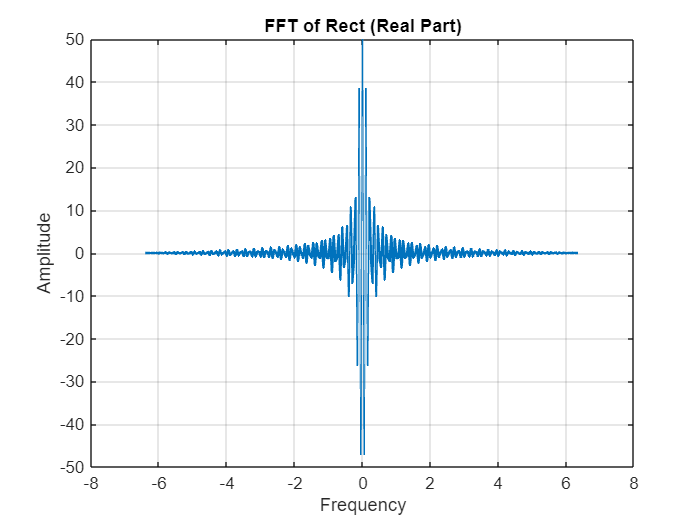


figure;
plot(f, real(Y_rect), 'LineWidth', 1.5);
title('FFT of Rect (Real Part)');
xlabel('Frequency');
ylabel('Amplitude');
grid on;

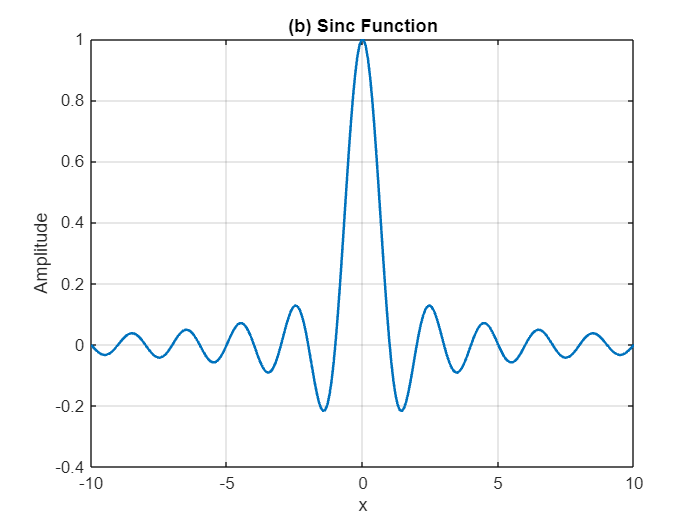


figure;
plot(x, y_sinc, 'LineWidth', 1.5);
title('(b) Sinc Function');
xlabel('x');
ylabel('Amplitude');
grid on;

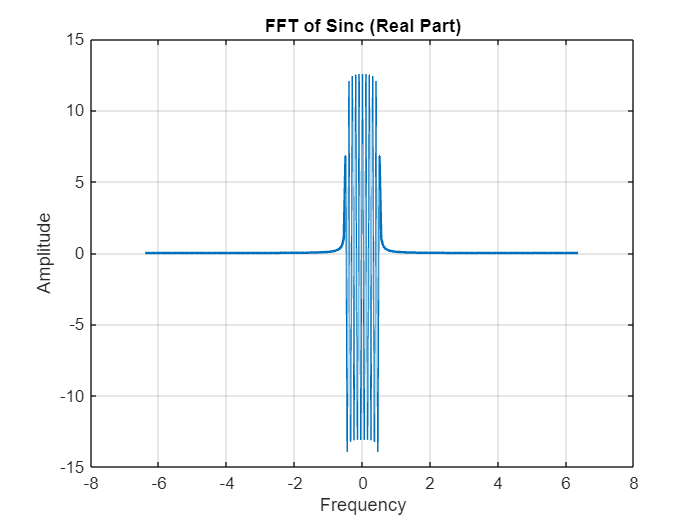


figure;
plot(f, real(Y_sinc), 'LineWidth', 1.5);
title('FFT of Sinc (Real Part)');
xlabel('Frequency');
ylabel('Amplitude');
grid on;

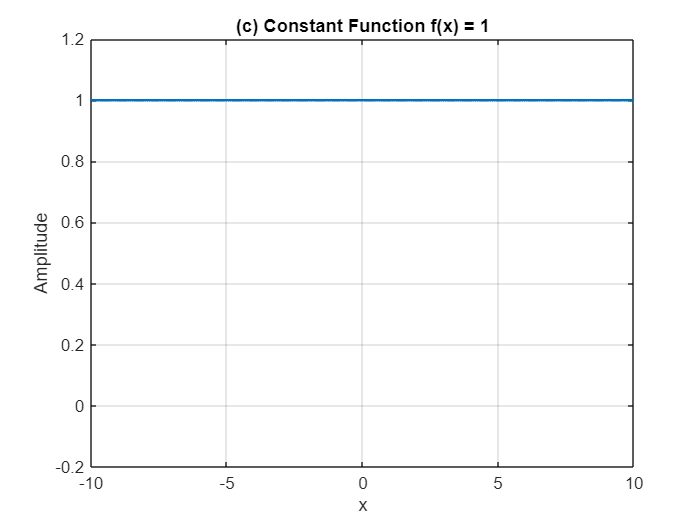


figure;
plot(x, y_const, 'LineWidth', 1.5);
title('(c) Constant Function f(x) = 1');
xlabel('x');
ylabel('Amplitude');
grid on;
ylim([-0.2, 1.2]);

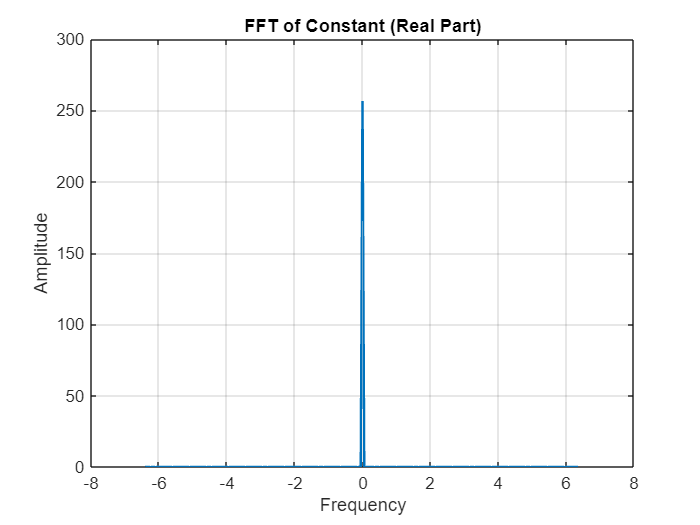


figure;
plot(f, real(Y_const), 'LineWidth', 1.5);
title('FFT of Constant (Real Part)');
xlabel('Frequency');
ylabel('Amplitude');
grid on;



fprintf('The Fourier transform of a Rect function is a Sinc function (sin(x)/x).\n');

The Fourier transform of a Rect function is a Sinc function (sin(x)/x).


fprintf('The resulting FFT plot shows a main lobe at the zero frequency with decaying side lobes, which is characteristic of a Sinc.\n\n');

The resulting FFT plot shows a main lobe at the zero frequency with decaying side lobes, which is characteristic of a Sinc.




fprintf('The Fourier transform of a Sinc function is a Rect function.\n');

The Fourier transform of a Sinc function is a Rect function.


fprintf('The FFT plot shows that the Sinc function is composed of a narrow band of low-frequency components.\n\n');

The FFT plot shows that the Sinc function is composed of a narrow band of low-frequency components.




fprintf('A constant signal has no change, so its frequency is zero. Its Fourier transform is a single spike at the zero frequency.\n');

A constant signal has no change, so its frequency is zero. Its Fourier transform is a single spike at the zero frequency.


fprintf('In the discrete case, this is a spike at the center of the DFT, representing a Dirac delta function.\n');

In the discrete case, this is a spike at the center of the DFT, representing a Dirac delta function.


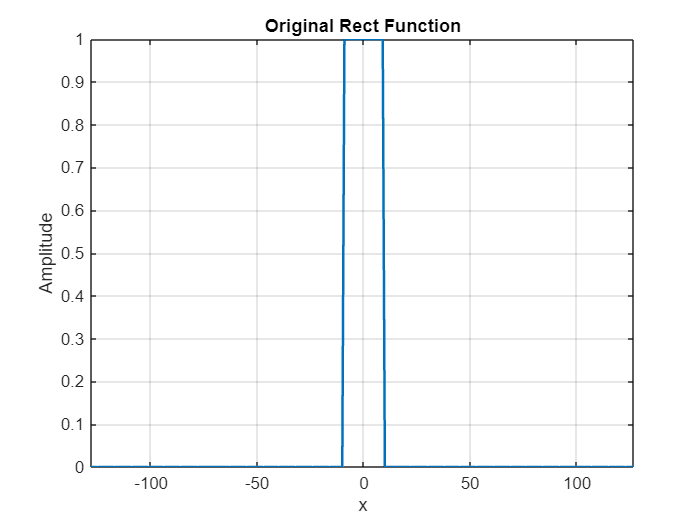

% 3.


N = 256;
x = linspace(-N/2, N/2 - 1, N);

rect_width = 20;
y_rect = zeros(1, N);
y_rect(abs(x) < rect_width/2) = 1;
Y_rect_fft = fft(fftshift(y_rect));

conv1_fft = Y_rect_fft .^ 2;
result1 = ifft(conv1_fft);
conv2_fft = Y_rect_fft .^ 3;
result2 = ifft(conv2_fft);
conv3_fft = Y_rect_fft .^ 4;
result3 = ifft(conv3_fft);

figure;
plot(x, y_rect, 'LineWidth', 1.5);
title('Original Rect Function');
xlabel('x');
ylabel('Amplitude');
grid on;
axis tight;

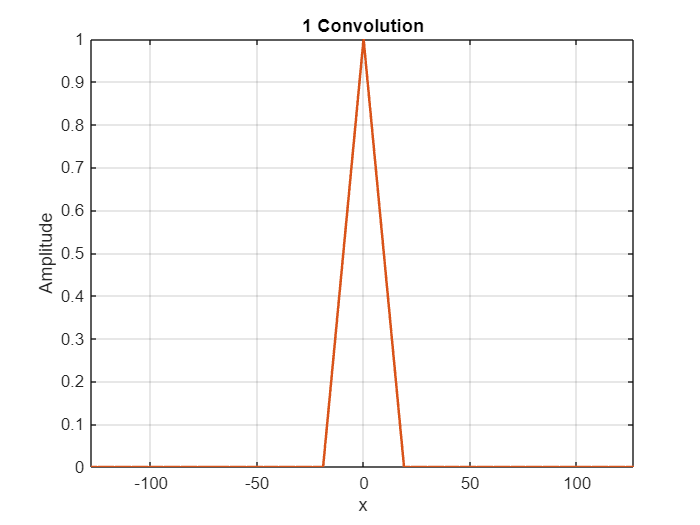


figure;
plot(x, fftshift(real(result1))/max(real(result1)), 'LineWidth', 1.5, 'Color', '#D95319');
title('1 Convolution');
xlabel('x');
ylabel('Amplitude');
grid on;
axis tight;

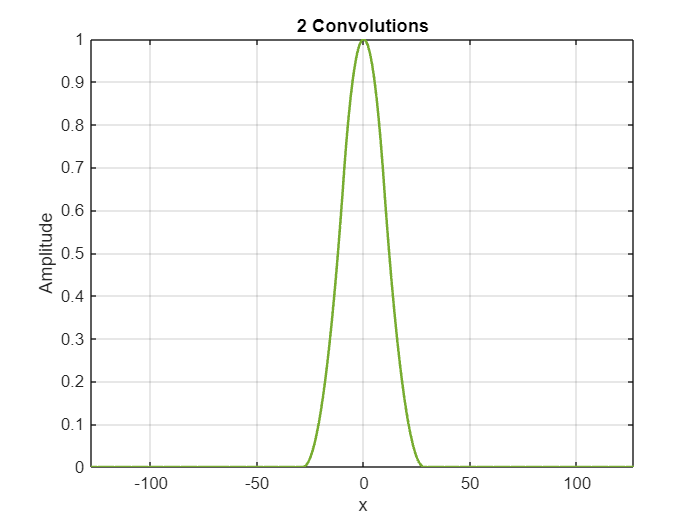


figure;
plot(x, fftshift(real(result2))/max(real(result2)), 'LineWidth', 1.5, 'Color', '#77AC30');
title('2 Convolutions');
xlabel('x');
ylabel('Amplitude');
grid on;
axis tight;

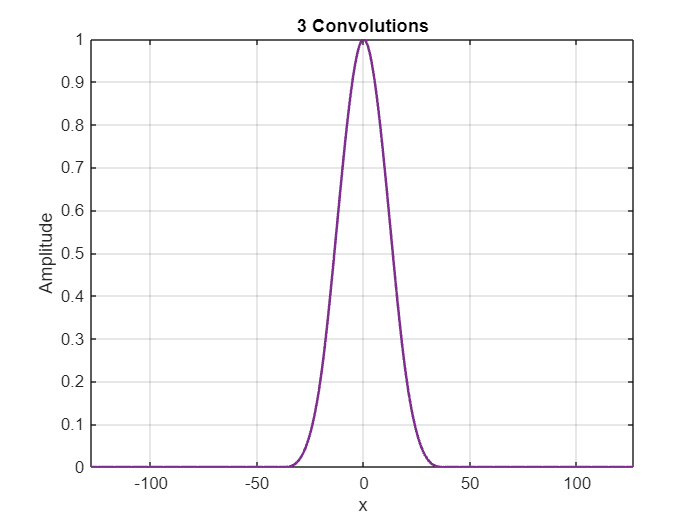


figure;
plot(x, fftshift(real(result3))/max(real(result3)), 'LineWidth', 1.5, 'Color', '#7E2F8E');
title('3 Convolutions');
xlabel('x');
ylabel('Amplitude');
grid on;
axis tight;


fprintf('The theorem states that convolution in the spatial domain is equivalent to simple point-wise multiplication in the frequency domain.\n');

The theorem states that convolution in the spatial domain is equivalent to simple point-wise multiplication in the frequency domain.


fprintf('F{f(x) * g(x)} = F(w) * G(w)\n');

F{f(x) * g(x)} = F(w) * G(w)


fprintf('This behavior is a demonstration of the Central Limit Theorem, which states that repeated convolutions will cause a function to approach a Gaussian shape.\n');

This behavior is a demonstration of the Central Limit Theorem, which states that repeated convolutions will cause a function to approach a Gaussian shape.


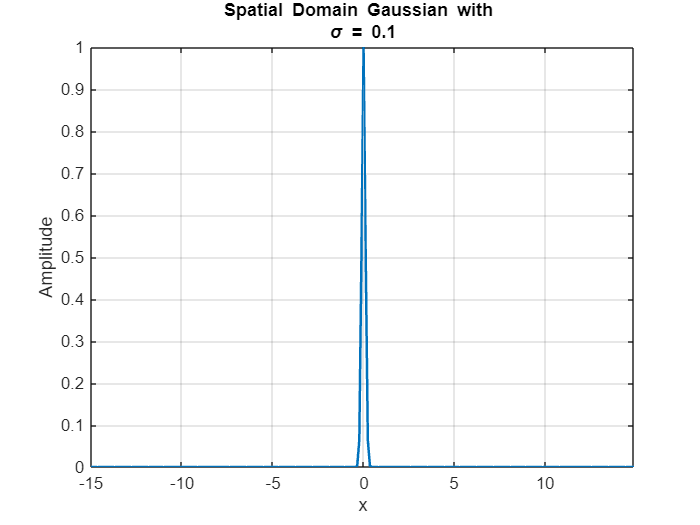

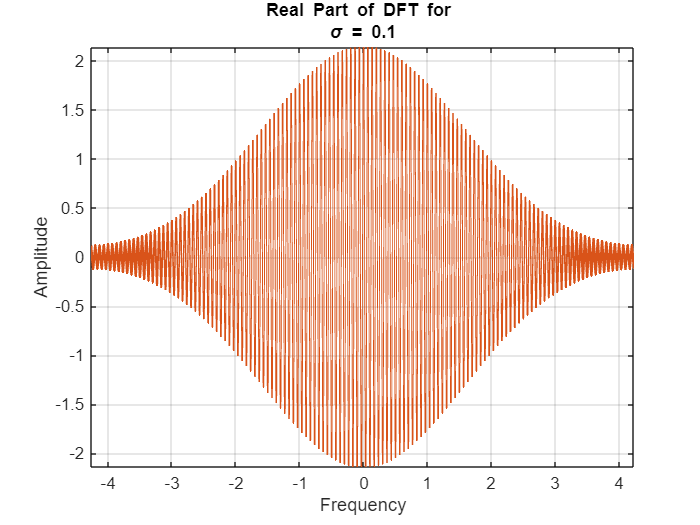

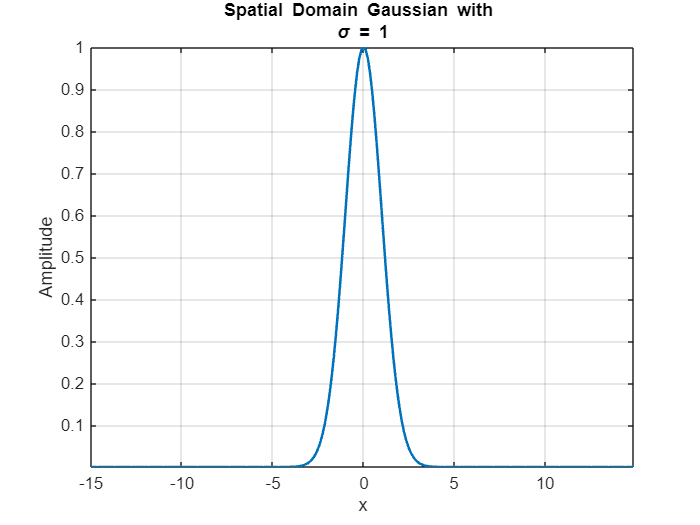

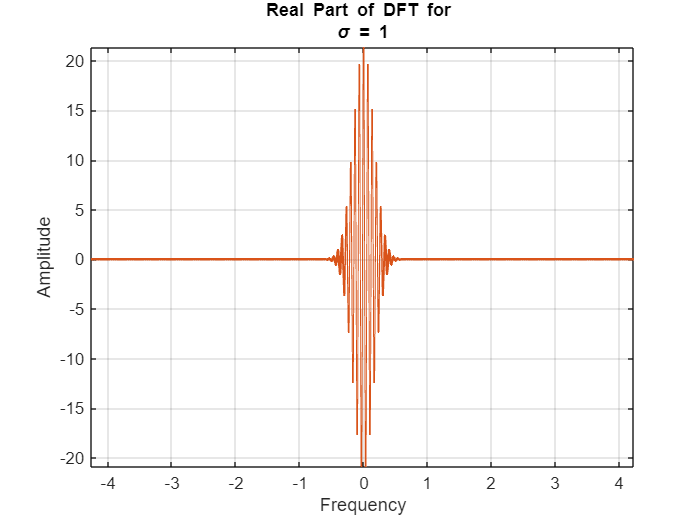

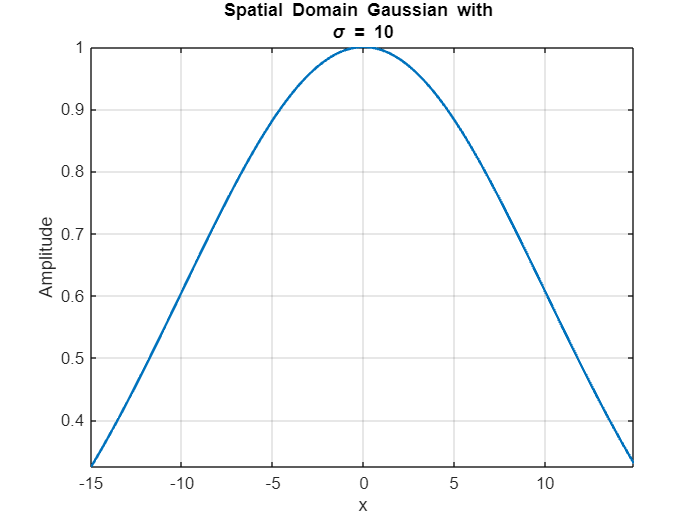

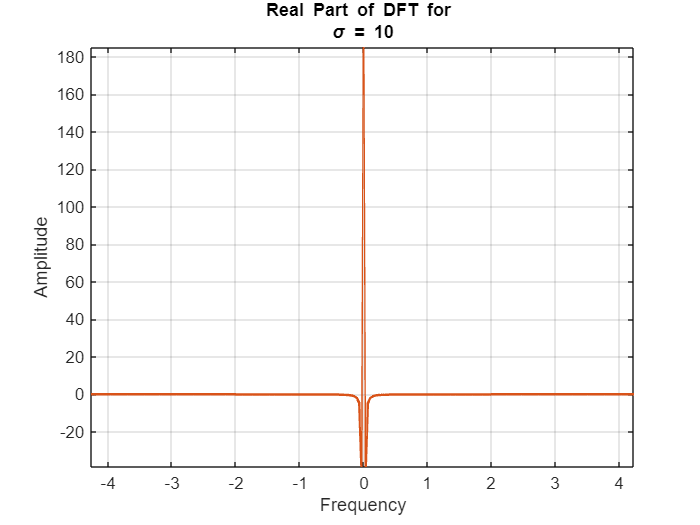

% 4. 


N = 256;
x = linspace(-15, 15, 257);
x = x(1:N);
fs = N / 30; 
f = (-N/2 : N/2-1) * (fs/N);
sigmas = [0.1, 1, 10];
titles = ["\sigma = 0.1", "\sigma = 1", "\sigma = 10"];

for i = 1:length(sigmas)
    sigma = sigmas(i);
    y_gauss = exp(-x.^2 / (2 * sigma^2));
    Y_gauss_fft = fftshift(fft(y_gauss));

    figure;
    plot(x, y_gauss, 'LineWidth', 1.5);
    title(['Spatial Domain Gaussian with ', titles(i)]);
    xlabel('x');
    ylabel('Amplitude');
    grid on;
    axis tight;

    figure;
    plot(f, real(Y_gauss_fft), 'LineWidth', 1.5, 'Color', '#D95319');
    title(['Real Part of DFT for ', titles(i)]);
    xlabel('Frequency');
    ylabel('Amplitude');
    grid on;
    axis tight;
end



fprintf('A very narrow, sharp Gaussian in space is composed of a very wide range of frequencies. Its DFT is a wide Gaussian.\n\n');

A very narrow, sharp Gaussian in space is composed of a very wide range of frequencies. Its DFT is a wide Gaussian.



fprintf('Large Sigma (10) - The ''Weird'' Result:\n');

Large Sigma (10) - The 'Weird' Result:


fprintf('A Gaussian with a very large sigma is too wide for our finite domain of [-15, 15].\n');

A Gaussian with a very large sigma is too wide for our finite domain of [-15, 15].


fprintf('The tails of the function that extend beyond the boundaries ''wrap around'' to the other side. This is called Aliasing.\n');

The tails of the function that extend beyond the boundaries 'wrap around' to the other side. This is called Aliasing.


fprintf('The resulting DFT is a very narrow Gaussian but with added high-frequency ripples or oscillations.\n');

The resulting DFT is a very narrow Gaussian but with added high-frequency ripples or oscillations.


% 5.


N = 256;         
T = 1;           
fs = N / T;     
t = (0:N-1) / fs; 
f_nyquist = fs / 2;
fprintf('Sampling Frequency: %.f Hz\n', fs);

Sampling Frequency: 256 Hz


fprintf('Nyquist Frequency: %.f Hz\n', f_nyquist);

Nyquist Frequency: 128 Hz


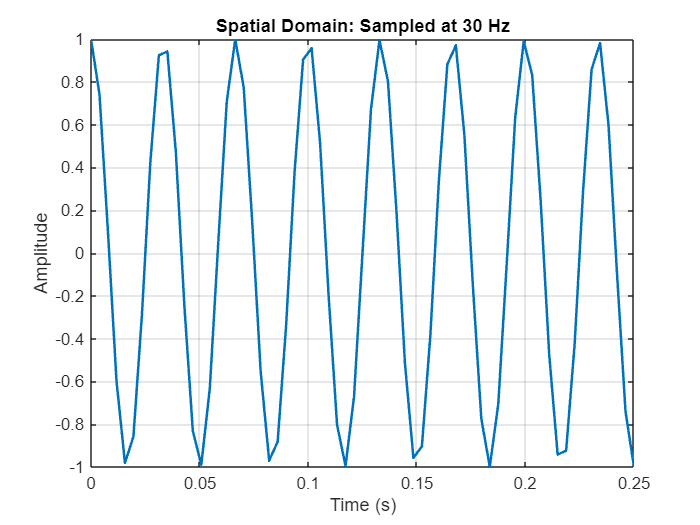


f_low = 30;     
f_high = fs - f_low; 

y_low = cos(2 * pi * f_low * t);
y_high = cos(2 * pi * f_high * t);

figure;
plot(t, y_low, 'LineWidth', 1.5);
title(['Spatial Domain: Sampled at ', num2str(f_low), ' Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
xlim([0, 0.25]); 

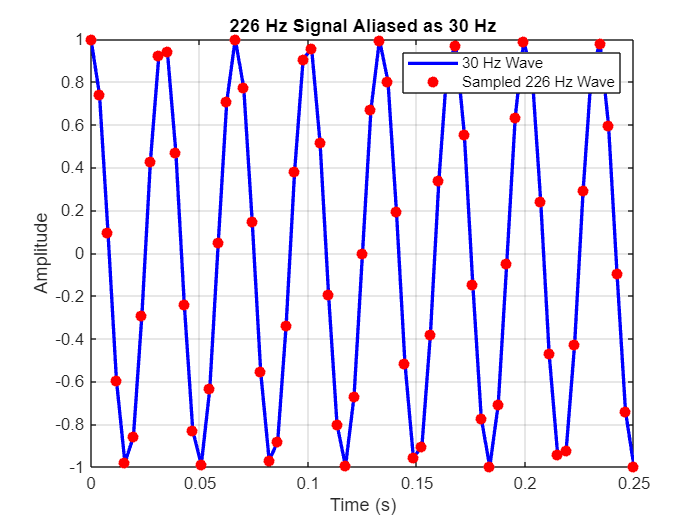


figure;
plot(t, y_low, 'b-', 'LineWidth', 2);
hold on;
plot(t, y_high, 'ro', 'MarkerFaceColor', 'r');
hold off;
title(['226 Hz Signal Aliased as 30 Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
legend([num2str(f_low), ' Hz Wave'], ['Sampled ', num2str(f_high), ' Hz Wave']);
grid on;
xlim([0, 0.25]);

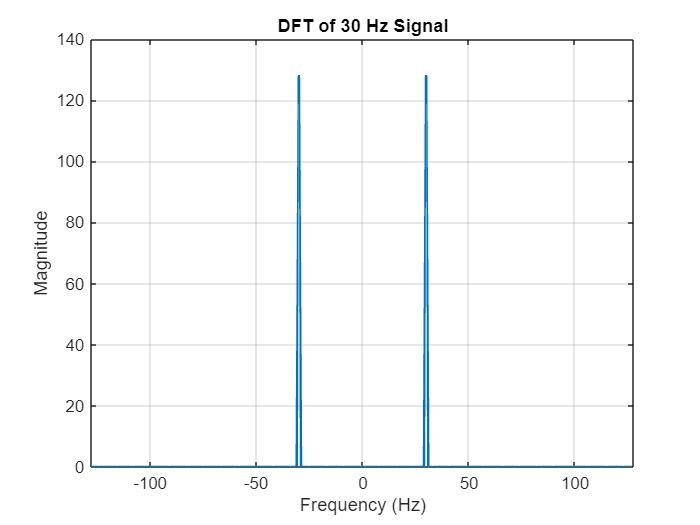


f_axis = (-N/2 : N/2-1) * (fs/N);

Y_low_fft = fftshift(fft(y_low));
figure;
plot(f_axis, abs(Y_low_fft), 'LineWidth', 1.5);
title(['DFT of ', num2str(f_low), ' Hz Signal']);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xlim([-fs/2, fs/2]);

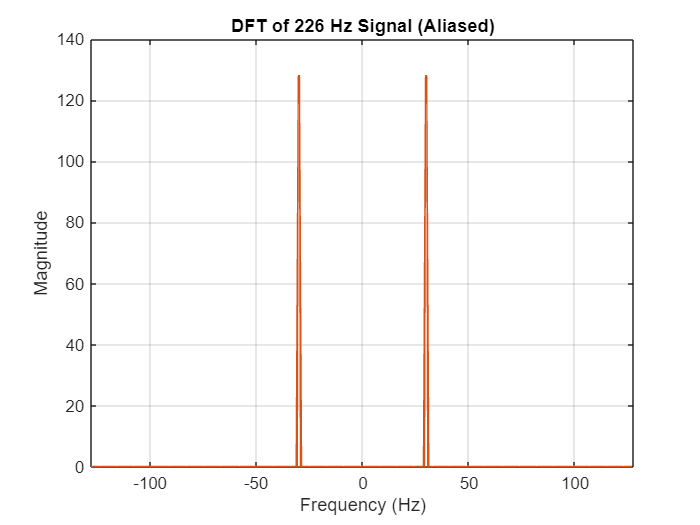



Y_high_fft = fftshift(fft(y_high));
figure;
plot(f_axis, abs(Y_high_fft), 'LineWidth', 1.5, 'Color', '#D95319');
title(['DFT of ', num2str(f_high), ' Hz Signal (Aliased)']);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xlim([-fs/2, fs/2]);



fprintf('Aliasing occurs when a signal is sampled too slowly. High frequencies are misrepresented as lower frequencies.\n');

Aliasing occurs when a signal is sampled too slowly. High frequencies are misrepresented as lower frequencies.


fprintf('With a sampling rate of 256 Hz, the Nyquist frequency is 128 Hz.\n');

With a sampling rate of 256 Hz, the Nyquist frequency is 128 Hz.


fprintf('A 226 Hz signal is above this limit. It aliases to a new frequency of |226 Hz - 256 Hz| = 30 Hz.\n\n');

A 226 Hz signal is above this limit. It aliases to a new frequency of |226 Hz - 256 Hz| = 30 Hz.



fprintf('In the SPATIAL domain, the sampled points of the 226 Hz wave fall exactly on top of a true 30 Hz wave.\n');

In the SPATIAL domain, the sampled points of the 226 Hz wave fall exactly on top of a true 30 Hz wave.


fprintf('In the FOURIER domain, the DFT of the 226 Hz signal incorrectly shows peaks at +/- 30 Hz, not +/- 226 Hz.\n');

In the FOURIER domain, the DFT of the 226 Hz signal incorrectly shows peaks at +/- 30 Hz, not +/- 226 Hz.


fprintf('The high-frequency information has been completely misinterpreted as low-frequency information.\n');

The high-frequency information has been completely misinterpreted as low-frequency information.


% 6.


N1 = 65536;
data1 = rand(1, N1);
num_trials = 1000;

tic;
for i = 1:num_trials
    fft(data1);
end
time1 = toc;

avg_time1 = time1 / num_trials;

fprintf('Vector Size: %d (2^16)\n', N1);

Vector Size: 65536 (2^16)


fprintf('Total time for %d FFTs: %.4f seconds\n', num_trials, time1);

Total time for 1000 FFTs: 0.6806 seconds


fprintf('Average FFT time: %.6f seconds\n\n', avg_time1);

Average FFT time: 0.000681 seconds




N2 = 65535;
data2 = rand(1, N2);

tic;
for i = 1:num_trials
    fft(data2);
end
time2 = toc;

avg_time2 = time2 / num_trials;

fprintf('Vector Size: %d\n', N2);

Vector Size: 65535


fprintf('Total time for %d FFTs: %.4f seconds\n', num_trials, time2);

Total time for 1000 FFTs: 2.7442 seconds


fprintf('Average FFT time: %.6f seconds\n\n', avg_time2);

Average FFT time: 0.002744 seconds




speed_difference = avg_time2 / avg_time1;
fprintf('The FFT for N=%d was approximately %.1f times faster than for N=%d.\n', N1, speed_difference, N2);

The FFT for N=65536 was approximately 4.0 times faster than for N=65535.



fprintf('When the input size is not a power of 2 (especially if it has large prime factors), the algorithm cannot be broken down efficiently.\n');

When the input size is not a power of 2 (especially if it has large prime factors), the algorithm cannot be broken down efficiently.


fprintf('For optimal performance, it is good to use input sizes that are a power of 2, often by padding the data with zeros.\n');

For optimal performance, it is good to use input sizes that are a power of 2, often by padding the data with zeros.
